This file runs an iterative search for the optimal solution to a simple 2D moving traveling salesman problem, inspired by [https://stackoverflow.com/questions/15485473/how-can-i-find-the-shortest-path-between-100-moving-targets-live-demo-included](https://stackoverflow.com/questions/15485473/how-can-i-find-the-shortest-path-between-100-moving-targets-live-demo-included)

Set up initial conditions for the problem instance: starting location for the chase vehicle, discrete-time loop paths for each "fish".  

DIM = 20; % Board size
MAX_TIME = 10000; % Initialize time-to-beat
myLoc = [3,5]; % Starting location for the chase vehicle
path1 = [11,11; 12,11; 13,11; 13,12; 13,13; 12,13; 11,13; 11,12]; % Paths each represent one fish's loop
path2 = [4,14; 4,15; 4,16; 4,17; 5,17; 5,16; 5,15; 5,14];
path3 = [8,8; 8,9; 9,9; 9,8; 9,7; 9,6; 8,6; 7,6; 7,7; 7,8];
fish = {path1, path2, path3};
% Longer demo with more fish - uncomment these two lines
path4 = [1,1; 1,2; 1,3; 1,4; 1,5; 1,6; 1,7; 1,6; 1,5; 2,5; 3,5; 4,5; 4,4; 4,3; 3,3; 3,2; 2,2; 2,1];
fish = {path1, path2, path3, path4};

Set up variables for the demo:

chaserLoc =      3     5


chaserLoc =      2     5


chaserLoc =      1     5


chaserLoc =      1     4


chaserLoc =      1     4


chaserLoc =      1     4


chaserLoc =      2     4


chaserLoc =      3     4


chaserLoc =      4     4


chaserLoc =      5     4


chaserLoc =      6     4


chaserLoc =      7     4


chaserLoc =      7     5


chaserLoc =      8     5


chaserLoc =      8     6


chaserLoc =      9     6


chaserLoc =      9     7


chaserLoc =      9     7


chaserLoc =      9     7


chaserLoc =      9     8


chaserLoc =      9     9


chaserLoc =      9    10


chaserLoc =      9    11


chaserLoc =      9    12


chaserLoc =      9    13


chaserLoc =      8    13


chaserLoc =      8    14


chaserLoc =      7    14


chaserLoc =      7    15


chaserLoc =      6    15


chaserLoc =      6    16


chaserLoc =      5    16


chaserLoc =      5    17


chaserLoc =      5    17


chaserLoc =      5    17


chaserLoc =      6    17


chaserLoc =      7    17


chaserLoc =      8    17


chaserLoc =      8    16


chaserLoc =      9    16


chaserLoc =      9    15


chaserLoc =     10    15


chaserLoc =     10    14


chaserLoc =     11    14


chaserLoc =     11    13


chaserLoc =     11    13


ans =      4     3     2     1


myTrack =      3     5
     1     4
     9     7
     5    17
    11    13


steps =      1     4    15    29    39


chaserLoc =      3     5


chaserLoc = 1×2
     2     5


chaserLoc = 1×2
     1     5


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     2     4


chaserLoc = 1×2
     3     4


chaserLoc = 1×2
     4     4


chaserLoc = 1×2
     5     4


chaserLoc = 1×2
     6     4


chaserLoc = 1×2
     7     4


chaserLoc = 1×2
     7     5


chaserLoc = 1×2
     8     5


chaserLoc = 1×2
     8     6


chaserLoc = 1×2
     9     6


chaserLoc = 1×2
     9     7


chaserLoc = 1×2
     9     7


chaserLoc = 1×2
     9     7


chaserLoc = 1×2
     9     8


chaserLoc = 1×2
     9     9


chaserLoc = 1×2
     9    10


chaserLoc = 1×2
     9    11


chaserLoc = 1×2
    10    11


chaserLoc = 1×2
    10    12


chaserLoc = 1×2
    11    12


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    10    13


chaserLoc = 1×2
     9    13


chaserLoc = 1×2
     8    13


chaserLoc = 1×2
     7    13


chaserLoc = 1×2
     6    13


chaserLoc = 1×2
     6    14


chaserLoc = 1×2
     5    14


chaserLoc = 1×2
     5    15


chaserLoc = 1×2
     5    15


ans = 1×4
     4     3     1     2


myTrack = 5×2
     3     5
     1     4
     9     7
    11    13
     5    15


steps = 1×5
     1     4    15    23    31


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     2     5


chaserLoc = 1×2
     1     5


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     5


chaserLoc = 1×2
     1     6


chaserLoc = 1×2
     1     7


chaserLoc = 1×2
     1     8


chaserLoc = 1×2
     1     9


chaserLoc = 1×2
     1    10


chaserLoc = 1×2
     1    11


chaserLoc = 1×2
     2    11


chaserLoc = 1×2
     2    12


chaserLoc = 1×2
     3    12


chaserLoc = 1×2
     3    13


chaserLoc = 1×2
     4    13


chaserLoc = 1×2
     4    14


chaserLoc = 1×2
     4    14


chaserLoc = 1×2
     4    14


chaserLoc = 1×2
     4    13


chaserLoc = 1×2
     4    12


chaserLoc = 1×2
     4    11


chaserLoc = 1×2
     4    10


chaserLoc = 1×2
     4     9


chaserLoc = 1×2
     5     9


chaserLoc = 1×2
     5     8


chaserLoc = 1×2
     6     8


chaserLoc = 1×2
     6     7


chaserLoc = 1×2
     7     7


chaserLoc = 1×2
     7     6


chaserLoc = 1×2
     7     6


chaserLoc = 1×2
     7     6


chaserLoc = 1×2
     7     7


chaserLoc = 1×2
     7     8


chaserLoc = 1×2
     7     9


chaserLoc = 1×2
     8     9


chaserLoc = 1×2
     8    10


chaserLoc = 1×2
     9    10


chaserLoc = 1×2
     9    11


chaserLoc = 1×2
    10    11


chaserLoc = 1×2
    10    12


chaserLoc = 1×2
    11    12


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


ans = 1×4
     4     2     3     1


myTrack = 5×2
     3     5
     1     4
     4    14
     7     6
    11    13


steps = 1×5
     1     4    17    28    39


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     2     5


chaserLoc = 1×2
     1     5


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     5


chaserLoc = 1×2
     1     6


chaserLoc = 1×2
     1     7


chaserLoc = 1×2
     1     8


chaserLoc = 1×2
     1     9


chaserLoc = 1×2
     1    10


chaserLoc = 1×2
     1    11


chaserLoc = 1×2
     2    11


chaserLoc = 1×2
     2    12


chaserLoc = 1×2
     3    12


chaserLoc = 1×2
     3    13


chaserLoc = 1×2
     4    13


chaserLoc = 1×2
     4    14


chaserLoc = 1×2
     4    14


chaserLoc = 1×2
     4    14


chaserLoc = 1×2
     5    14


chaserLoc = 1×2
     6    14


chaserLoc = 1×2
     7    14


chaserLoc = 1×2
     8    14


chaserLoc = 1×2
     9    14


chaserLoc = 1×2
    10    14


chaserLoc = 1×2
    11    14


chaserLoc = 1×2
    12    14


chaserLoc = 1×2
    12    13


chaserLoc = 1×2
    13    13


chaserLoc = 1×2
    13    12


chaserLoc = 1×2
    13    12


chaserLoc = 1×2
    13    12


chaserLoc = 1×2
    12    12


chaserLoc = 1×2
    11    12


chaserLoc = 1×2
    11    11


chaserLoc = 1×2
    10    11


chaserLoc = 1×2
    10    10


chaserLoc = 1×2
     9    10


chaserLoc = 1×2
     9     9


chaserLoc = 1×2
     8     9


chaserLoc = 1×2
     8     8


chaserLoc = 1×2
     7     8


chaserLoc = 1×2
     7     7


chaserLoc = 1×2
     7     7


ans = 1×4
     4     2     1     3


myTrack = 5×2
     3     5
     1     4
     4    14
    13    12
     7     7


steps = 1×5
     1     4    17    28    39


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     2     5


chaserLoc = 1×2
     1     5


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     2     4


chaserLoc = 1×2
     3     4


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     4     6


chaserLoc = 1×2
     5     6


chaserLoc = 1×2
     5     7


chaserLoc = 1×2
     6     7


chaserLoc = 1×2
     6     8


chaserLoc = 1×2
     7     8


chaserLoc = 1×2
     7     9


chaserLoc = 1×2
     8     9


chaserLoc = 1×2
     8    10


chaserLoc = 1×2
     9    10


chaserLoc = 1×2
     9    11


chaserLoc = 1×2
    10    11


chaserLoc = 1×2
    10    12


chaserLoc = 1×2
    11    12


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    12


chaserLoc = 1×2
    11    11


chaserLoc = 1×2
    10    11


chaserLoc = 1×2
    10    10


chaserLoc = 1×2
     9    10


chaserLoc = 1×2
     9     9


chaserLoc = 1×2
     8     9


chaserLoc = 1×2
     8     8


chaserLoc = 1×2
     8     8


chaserLoc = 1×2
     8     8


chaserLoc = 1×2
     8     9


chaserLoc = 1×2
     8    10


chaserLoc = 1×2
     8    11


chaserLoc = 1×2
     7    11


chaserLoc = 1×2
     7    12


chaserLoc = 1×2
     6    12


chaserLoc = 1×2
     6    13


chaserLoc = 1×2
     5    13


chaserLoc = 1×2
     5    14


chaserLoc = 1×2
     5    14


ans = 1×4
     4     1     3     2


myTrack = 5×2
     3     5
     1     4
    11    13
     8     8
     5    14


steps = 1×5
     1     4    23    31    40


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     2     5


chaserLoc = 1×2
     1     5


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     1     4


chaserLoc = 1×2
     2     4


chaserLoc = 1×2
     3     4


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     4     6


chaserLoc = 1×2
     5     6


chaserLoc = 1×2
     5     7


chaserLoc = 1×2
     6     7


chaserLoc = 1×2
     6     8


chaserLoc = 1×2
     7     8


chaserLoc = 1×2
     7     9


chaserLoc = 1×2
     8     9


chaserLoc = 1×2
     8    10


chaserLoc = 1×2
     9    10


chaserLoc = 1×2
     9    11


chaserLoc = 1×2
    10    11


chaserLoc = 1×2
    10    12


chaserLoc = 1×2
    11    12


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    10    13


chaserLoc = 1×2
     9    13


chaserLoc = 1×2
     8    13


chaserLoc = 1×2
     7    13


chaserLoc = 1×2
     6    13


chaserLoc = 1×2
     6    14


chaserLoc = 1×2
     5    14


chaserLoc = 1×2
     5    15


chaserLoc = 1×2
     5    15


chaserLoc = 1×2
     5    15


chaserLoc = 1×2
     5    14


chaserLoc = 1×2
     5    13


chaserLoc = 1×2
     5    12


chaserLoc = 1×2
     5    11


chaserLoc = 1×2
     5    10


chaserLoc = 1×2
     6    10


chaserLoc = 1×2
     6     9


chaserLoc = 1×2
     7     9


chaserLoc = 1×2
     7     8


chaserLoc = 1×2
     7     8


ans = 1×4
     4     1     2     3


myTrack = 5×2
     3     5
     1     4
    11    13
     5    15
     7     8


steps = 1×5
     1     4    23    31    40


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     5     5


chaserLoc = 1×2
     6     5


chaserLoc = 1×2
     7     5


chaserLoc = 1×2
     8     5


chaserLoc = 1×2
     8     6


chaserLoc = 1×2
     8     6


chaserLoc = 1×2
     8     6


chaserLoc = 1×2
     7     6


chaserLoc = 1×2
     6     6


chaserLoc = 1×2
     5     6


chaserLoc = 1×2
     4     6


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     4     6


chaserLoc = 1×2
     4     7


chaserLoc = 1×2
     4     8


chaserLoc = 1×2
     4     9


chaserLoc = 1×2
     4    10


chaserLoc = 1×2
     4    11


chaserLoc = 1×2
     4    12


chaserLoc = 1×2
     4    13


chaserLoc = 1×2
     4    14


chaserLoc = 1×2
     5    14


chaserLoc = 1×2
     5    15


chaserLoc = 1×2
     5    15


chaserLoc = 1×2
     5    15


chaserLoc = 1×2
     6    15


chaserLoc = 1×2
     7    15


chaserLoc = 1×2
     8    15


chaserLoc = 1×2
     9    15


chaserLoc = 1×2
    10    15


chaserLoc = 1×2
    10    14


chaserLoc = 1×2
    11    14


chaserLoc = 1×2
    11    13


chaserLoc = 1×2
    11    13


ans = 1×4
     3     4     2     1


myTrack = 5×2
     3     5
     8     6
     4     5
     5    15
    11    13


steps = 1×5
     1     7    12    23    31


chaserLoc = 1×2
     3     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     5     5


chaserLoc = 1×2
     6     5


chaserLoc = 1×2
     7     5


chaserLoc = 1×2
     8     5


chaserLoc = 1×2
     8     6


chaserLoc = 1×2
     8     6


chaserLoc = 1×2
     8     6


chaserLoc = 1×2
     7     6


chaserLoc = 1×2
     6     6


chaserLoc = 1×2
     5     6


chaserLoc = 1×2
     4     6


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     4     5


chaserLoc = 1×2
     5     5


chaserLoc = 1×2
     6     5


chaserLoc = 1×2
     6     6


chaserLoc = 1×2
     7     6


chaserLoc = 1×2
     7     7


chaserLoc = 1×2
     8     7


chaserLoc = 1×2
     8     8


chaserLoc = 1×2
     9     8


chaserLoc = 1×2
     9     9


chaserLoc = 1×2
    10     9


chaserLoc = 1×2
    10    10


chaserLoc = 1×2
    11    10


chaserLoc = 1×2
    11    11


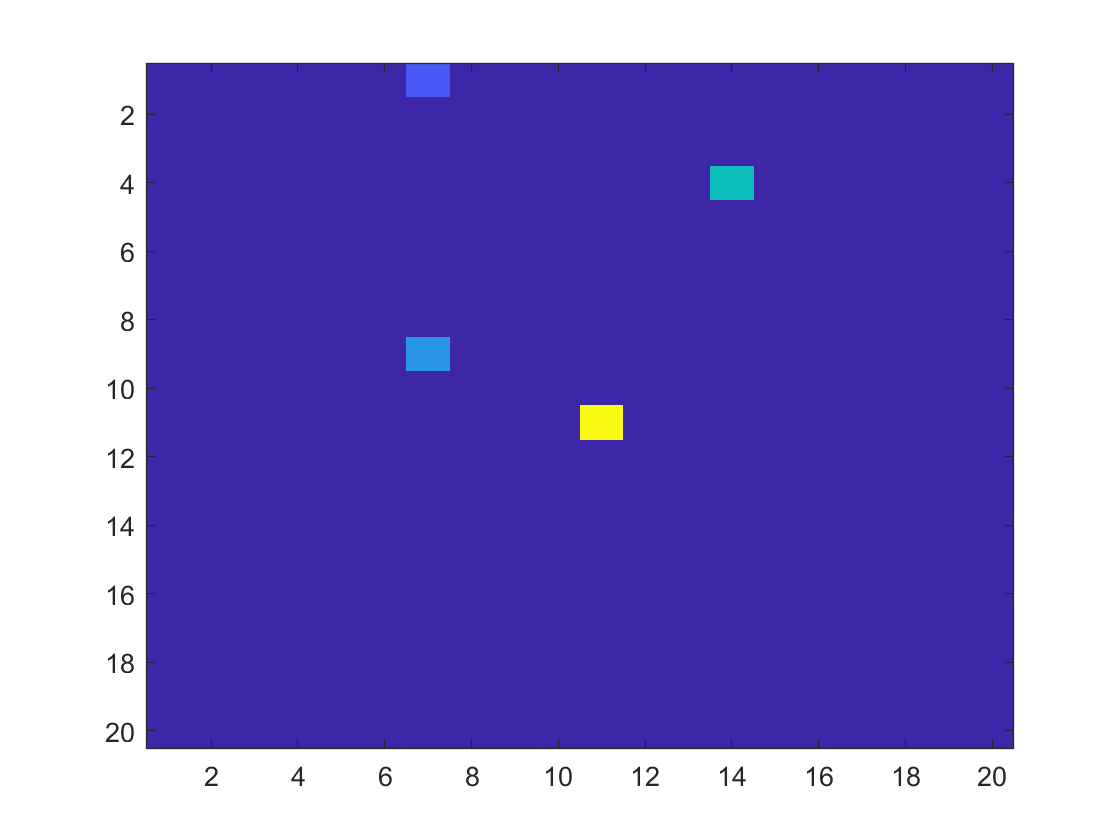

chaserLoc = 1×2
    11    11


myTrack = zeros(size(fish,2)+1,2);
myTrack(1,:)=myLoc;
steps = ones(1,size(fish,2)+1);
sequence = 1:size(fish,2);
permutations = perms(sequence); % This allows us to loop through all possible pursuit sequences
bestTrack = myTrack; % Initialize variables to store the best sequence found so far
bestSteps = steps;
bestSteps(size(fish,2)+1) = MAX_TIME;
figure;
set(gcf,'Visible','on');
hold on
% Loop through all sequences
for jx=1:size(permutations,1)
    % Get time and location of each fish intercept in the given sequence
    for ix=1:size(fish,2)
        [time, loc] = fishIntercept(permutations(jx,ix), myTrack(ix,:), steps(ix), fish);
        steps(ix+1) = time;
        myTrack(ix+1,:)=loc;
    end
    % Draw the board for visualization (comment this loop out to speed up
    % the program)
    for round=1:size(fish,2)
        chaserLoc = myTrack(round,:)
        for timer=steps(round):steps(round+1)
            drawBoard(timer, chaserLoc, fish, DIM)
            chaserLoc = chaserStep(chaserLoc, myTrack(round+1,:))
            pause(0.1) % Increase this to slow down the animation
        end
    end
    pause(1)
    % Comment out the next three lines to skip printing data for each
    % sequence
    permutations(jx,:)
    myTrack
    steps
    if steps(size(fish,2)+1) < bestSteps(size(fish,2)+1)
        bestSteps = steps;
        bestTrack = myTrack;
        sequence = permutations (jx,:);
    end
end

Intercept locations and times:

bestTrack
bestSteps
sequence

Given a time-step, location of the chase vehicle, the fish paths, and the board dimension, draw the current state.

function drawBoard(time, myTrack, allFish, DIM)
    board = zeros(DIM);
    for ix=1:size(allFish,2)
        loc = fishLocation(ix,time,allFish);
        board(loc(1),loc(2)) = 170-(170/size(allFish,2)*(ix-1));
    end
    board(myTrack(1),myTrack(2)) = board(myTrack(1),myTrack(2))+200;
    image(board)
end

Find the location and time of intercept for the shortest path to a fish, given the current time and the location of the chase vehicle.

function [time, fishLoc] = fishIntercept(fishNum, currLoc, currTime, allFish)
    time = currTime;
    fishLoc = fishLocation(fishNum, time, allFish);
    while (pdist2(fishLoc,currLoc,'cityblock')> (time-currTime))
        time = time + 1;
        fishLoc = fishLocation(fishNum, time, allFish);
    end
end

Get the location of a particular fish at a time-step.

function loc = fishLocation(fishNum, time, allFish)
    fish = allFish{fishNum};
    sz = size(fish,1);
    ix = mod(time, sz);
    if ix == 0 
        ix = sz;
    end
    loc = fish(ix,:);
end

function chaserLocNew = chaserStep(chaserLoc, myTrack)
    chaserLocNew = chaserLoc;
    dist = chaserLoc-myTrack;
    [maxDist, xy] = max(abs(dist));
    if (dist(xy)>0) 
        chaserLocNew(xy)=chaserLocNew(xy)-1;
    elseif (dist(xy)<0)
        chaserLocNew(xy)=chaserLocNew(xy)+1;
    end

end